# 绘制gif图

基本思想：先生成多张静态图，然后组合成gif图

x1 = linspace(0, 1, 10000);
y1 = (1-x1.^2).^0.5;
plot(x1, y1); axis square;
x2 = rand([1, 500]);
y2 = rand([1, 500]);
plot(x1, y1, x2, y2, '.'); axis square
x2 = rand([1, 500]);
y2 = rand([1, 500]);

count = 0;
for j = 1:500
    if x2(j)^2 + y2(j)^2 <= 1
        count =count + 1;
    end
end

plot(x1, y1, x2, y2, ".");
title(num2str(count) + " / " + num2str(500) + "*" + "4" + "=" + num2str(count/500*4));
axis square;

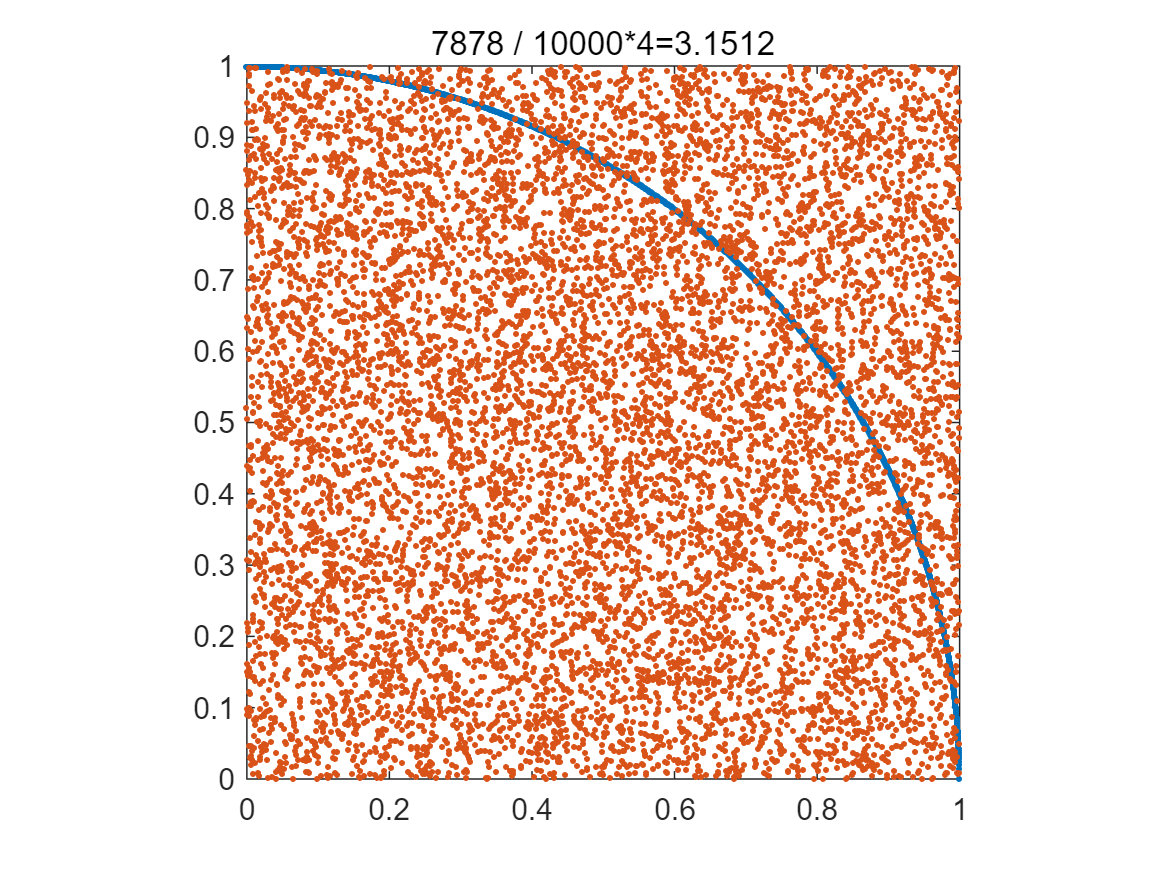

for i = [500, 1000, 5000, 10000]

    x1 = linspace(0, 1, 10000);
    y1 = (1-x1.^2).^0.5;
    x2 = rand([1, i]);
    y2 = rand([1, i]);

    count = 0;
    for j = 1:i
        if x2(j)^2 + y2(j)^2 <= 1
            count =count + 1;
        end
    end

    plot(x1, y1, '.', x2, y2, ".");
    title(num2str(count) + " / " + num2str(i) + "*" + "4" + "=" + num2str(count/i*4));
    axis square;

    %% 合成gif的固定代码
    frame = getframe(gcf);      %捕获坐标区或图窗作为影片帧
    I = frame2im(frame);        %返回与影片帧关联的图像数据
    [I, map] = rgb2ind(I, 256);  %将RGB图像转换为索引图像I，关联颜色图为map

    if i == 500
        imwrite(I, map, 'test.gif', 'gif', 'LoopCount', inf, 'DelayTime',0.5);
    else
        imwrite(I, map, 'test.gif', 'gif', 'WriteMode', 'append', 'DelayTime',0.5);
    end
end